# 9. 画像のノイズモデル

今回は，画像のノイズ（雑音）モデルについて学ぶ．特に原画素値にノイズが加算される，加法性ノイズに関して見ていこう．

clear;
figure;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## ガウス性ノイズモデル (Gaussian noise model)

最も典型的なノイズモデルは，クリーンな画像に平均 $0$ 標準偏差 $\sigma$ の白色ガウス性ノイズを加えるというものである．ガウス性ノイズは最も一般的なノイズであり，画像の場合は照度やセンサの温度等によって生じる．

読み込んだ画像に標準偏差 $\sigma = 0.1$ の白色ガウス性ノイズを加える．

name = 'house';
u = load_image(name,[]);
u = u/255; % 画素値の範囲を [0,1] に正規化
n = length(u);
N = n^2;
sigma = 0.1;

help randn

 randn Normally distributed pseudorandom numbers.
    R = randn(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard normal distribution.  randn(M,N) or randn([M,N]) returns
    an M-by-N matrix. randn(M,N,P,...) or randn([M,N,P,...]) returns an
    M-by-N-by-P-by-... array. randn returns a scalar.  randn(SIZE(A)) returns
    an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = randn(..., CLASSNAME) returns an array of normal values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = randn(..., 'like', Y) returns an array of normal values with
    the same data type and complexity (real or complex) as the numeric
    variable Y.
 
    The sequence of numbers prod

v = u + randn(n,n)*sigma;

画像を表示．

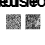

figure;
imageplot(v-u, 'Noise', 1,2,1); % ノイズのみを表示
imageplot(v, 'Observed noisy image', 1,2,2);

ノイズの統計情報を表示．

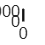

figure;
nbins = 201;
histogram( v(:)-u(:), nbins ); %ノイズ成分のヒストグラム

## インパルス性ノイズモデル (salt-and-pepper noise model)

各画素が一定の確率で白飛び or 黒飛びするノイズをインパルス性ノイズと呼ぶ（ごま塩ノイズとも呼ばれる）．画像の場合，センサの故障や誤作動により生じる．

画像に確率0.05で発生するごま塩ノイズを加える．

v = imnoise(u, 'salt & pepper', 0.05);

画像を表示．

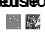

figure;
imageplot(v-u, 'Noise', 1,2,1);
imageplot(v, 'Observed noisy image', 1,2,2);

## ポアソン性ノイズモデル (Poisson noise model)

クリーンな画像 $\mathbf{u}$ の各画素値を $u_i$ とする．ポアソン性ノイズモデルでは，ノイズに汚染された観測画像 $\mathbf{v}$ の各画素値 $v_i$ がパラメータ $\lambda=u_i$ のポアソン分布から抽出されたサンプルであると考える．


$$\mbox{Poiss}(v_i=k)=\frac{\lambda^k e^{-\lambda}}{k!}$$


このノイズモデルは光子のカウント（ショットノイズ）に対応しており，$\lambda$ は露光時間中にレセプターに当たった光子の数に比例する．具体的には，医用画像（共焦点レーザー顕微鏡），PETやSPECT等の[断層撮影](https://ja.wikipedia.org/wiki/%E3%82%B3%E3%83%B3%E3%83%94%E3%83%A5%E3%83%BC%E3%82%BF%E6%96%AD%E5%B1%A4%E6%92%AE%E5%BD%B1)，デジタルカメラのノイズなどのモデリングに適している．

光子のカウント数が十分に多いとき，すなわち $\lambda$ が大きくなるにつれ，ポアソン分布はガウス分布に近づく．$\lambda=u_i$ は分布の平均値であるとともに分散でもあるので，観測画像の各画素に乗りうるノイズの強度は元の画素値に比例する．

いくつかの $\lambda$ に対するポアソン分布を表示．

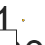

lambda = [4 10 20];
[k,Lambda] = meshgrid(1:50, lambda);
P = Lambda.^k .* exp(-Lambda)./factorial(k);
figure;
h = plot(P'); axis('tight');
set(h, 'LineWidth', 2);
legend('\lambda=4', '\lambda=10', '\lambda=20');
set_label('k', 'P(k)');

画像を読み込み，取りうる $\lambda$ の幅 $[\lambda_{min}, \lambda_{max}]$ で画素値を量子化する．

name = 'house';
u = load_image(name,[]);
lmin = 1;
lmax = 20;
ul = floor( rescale(u,lmin,lmax) );

ポアソン性ノイズを付加し，表示する．

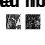

v = poissrnd(ul);
figure;
imageplot(ul, 'Original image', 1,2,1);
imageplot(v,  'Observed noisy image', 1,2,2);

差分を表示すると，ノイズレベルが強度に依存していることがわかる．明るいところではノイズが大きくなる．

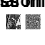

figure;
imageplot(ul, 'Original image', 1,2,1);
imageplot(v-ul,  'Poisson noise', 1,2,2);

## 演習問題

**演習7-1**: パラメータ$\lambda_{\max}$を $\lambda_{\max} = 5, 25, 128, 256$ と変化させた場合のポアソン性ノイズ（ $\lambda_{\min} = 1$ に固定）を，関数 `poissrnd `を利用し，画像"house"に重畳せよ．さらに，ポアソン性ノイズを重畳した画像"house"を，$2\times 2$ のグリッドに表示せよ．また，それぞれの場合におけるノイズのヒストグラムを $2\times 2$ のグリッドに表示し， $\lambda_{\max}$ を大きくするほどガウス性ノイズに近づくことを確認せよ．

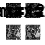

name = 'house';
u = load_image(name,[]);
lmin = 1;
lambda_max = [5,25,128,256];
figure;
for i = 1:4
    lmax = lambda_max(i);
    ul = floor( rescale(u,lmin,lmax) );
    v = poissrnd(ul);
    imageplot(v,  ['lmax=',num2str(lmax)], 2,2,i);
end

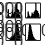



figure;
nbins = 201;
for i = 1:4
    lmax = lambda_max(i);
    ul = floor( rescale(u,lmin,lmax) );
    v = poissrnd(ul);
    subplot(2,2,i);
    histogram( v(:)-u(:), nbins );

end